When starting from saved variables, begin from section 1.1-2.

0-1  Set user-defined parameters and load data

% =====================================================================
% LassoGLM Sparse Modeling Pipeline
% =====================================================================
% Equivalent to DiffDiet_3_elasticnet_mapper.ipynb (ElasticNetCV sections).
% Sections 1.2-x are not used in the published analysis.
%
% How to use this Live Script:
%   - Run sections sequentially using Ctrl+Enter (Run Section).
%   - After 1.1-1 and 1.1-2, inspect the plots, then set
%     Selected_L1rate in section 1.1-3 before continuing.
%   - Do NOT use Run All: intermediate results must be checked first.
% =====================================================================

% ---- USER-DEFINED PARAMETERS ----------------------------------------
% Filename of the ASV CSV file (must be in the same folder as this script).
file_name = 'ASV_DiffDiet.csv';

% Gut region to analyze.
gut = 'intestine';

% Population to analyze. Options: 'SF'  'Pa'  'Mo'  'F1sp'  'F1sm'
pop2 = 'Mo';

% Morphometric trait (response variable Y).
% Options: 'StandardLength', 'std_HindgutLength',
%          'std_MidgutWidth', 'std_TotalGutLength'
s = 'std_MidgutWidth';

% Consistency rate: fraction of repeats an ASV must appear in to be
% considered reliably selected (used in section 1.1-2).
appearanceRate = 0.8;
% ---------------------------------------------------------------------

currentDir = pwd;
dir = currentDir;

(cont.) Data preprocessing

% Load full dataset
T_all = readtable(fullfile(currentDir, file_name));


% Filter by gut region and population
T = T_all(matches(T_all.gut, gut),:);
T = T(matches(T.pop2, pop2),:);

% Remove samples missing the morphometric trait
T = rmmissing(T,'DataVariables',{s});
Y = T(:,[s]);

% Column index of the last metadata column (just before ASV columns begin).
% Update 'std_MidgutWidth' to match the last metadata column in your dataset.
morp_ind = find(strcmp(T.Properties.VariableNames, 'std_MidgutWidth'));;

% Remove ASVs present in only one sample (insufficient for regression)
ind_moreThan0ASV=table2array(sum(T(:,morp_ind+1:end)>0))>1;

X_ori=T(:,morp_ind+1:size(T,[2]));

% Replace exact 1 values slightly to avoid log2(1)=0 being treated as absence
asvNum1=T(:,morp_ind+1:end)==1;
asvNum1=double(table2array(asvNum1))*0.0001;
X_ori=X_ori+asvNum1;
X_ori=X_ori(:,ind_moreThan0ASV);

% Log2-transform ASV counts; replace -Inf (from log2(0)) with 0
X=log2(X_ori);
XX = table2array(X);
XX(isinf(XX)) =0;
X(:,:)=num2cell(XX);
ASV=X.Properties.VariableNames;

fprintf('Data loaded: %d samples, %d ASVs\n', size(X,1), size(X,2));

Data loaded: 32 samples, 797 ASVs


0-2  (Optional) Load Mapper nodes and filter samples

[file, path] = uigetfile({'*.pickle'}, ...
    'Select Mapper nodes pickle file. Click Cancel to use all samples.', dir);

if ~isequal(file,0)   % uigetfile returns 0 when Cancel is clicked
    pyenv(Version='3.11');
    fid = py.open(append(path,file), 'rb');
    nodes = py.pickle.load(fid);

    [file2, path2] = uigetfile({'*.txt'}, ...
        'Select "include" or "remove" cluster info file', path);

    if isequal(file2,0)
        error('No cluster info file selected.');
    end

    clusters = py.list();

    % Verify the cluster file matches the selected population and trait
    if count(file2,append('_',pop2,'_'))==0 | count(file2,append('_',s,'_'))==0
        error('Population or trait in cluster filename does not match settings.');
    end

    % Parse cluster info file:
    %   Multiple '_cuN_cl' patterns -> minPath-style node name file
    %   Otherwise -> tab-separated [cube_index, cluster_index] file
    if length(regexp(file2,'_cu.?_cl')) > 1
        cluster_info = readlines(append(path2,file2));
        for i = 1:size(cluster_info,1)
            if cluster_info(i) ~= ""
                node_list = nodes.get(cluster_info(i));
                clusters.extend(node_list);
            end
        end
    else
        cluster_info = readmatrix(append(path2,file2));
        for i = 1:size(cluster_info,1)
            node_list = nodes.get(append('cube',num2str(cluster_info(i,1)), ...
                '_cluster',num2str(cluster_info(i,2))));
            clusters.extend(node_list);
        end
    end

    % Remove duplicate sample indices (samples belonging to multiple nodes)
    clusters = py.list(py.set(clusters));
    clusters = double(clusters);
    clusters = clusters + 1; % Adjust Python 0-based index to MATLAB 1-based

    if contains(file2,'remove')==1 | contains(file2,'Remove')==1
        % Remove selected samples
        X(clusters,:) = [];
        ind_moreThan0ASV = table2array(sum(X>0)) > 1;
        X = X(:,ind_moreThan0ASV);
        Y(clusters,:) = [];
        ASV = ASV(ind_moreThan0ASV);
    else
        % Keep only the selected samples
        X = X(clusters,:);
        ind_moreThan0ASV = table2array(sum(X>0)) > 1;
        X = X(:,ind_moreThan0ASV);
        Y = Y(clusters,:);
        ASV = ASV(ind_moreThan0ASV);
    end
end

1.1-1  Grid search for L1 rate with 10 repeats  [Run Section only - takes ~25 min]

Xa=table2array(X);
Ya=table2array(Y);

% L1 rates (alpha) and repeat indices for grid search
alphas=[ 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1.0];
repeat=[1:10];

% Run lassoglm for all (alpha, repeat) combinations with 10-fold CV.
% Parallelized with parfor (Parallel Computing Toolbox required).
% parfor distributes the 100 jobs (10 alphas x 10 repeats) across
% available CPU cores, significantly reducing computation time.
% If Parallel Computing Toolbox is not available, replace parfor with for.
[A, R] = ndgrid(alphas, repeat);
n_jobs = numel(A);
clfs    = cell(size(A));
FitInfos = cell(size(A));

parfor k = 1:n_jobs
    clfs{k}     = [];
    FitInfos{k} = [];
    [clfs{k}, FitInfos{k}] = lassoglm(Xa, Ya, 'normal', 'Alpha', A(k), 'CV', 10);
end

% Extract summary statistics across the grid
a_ind=[1:size(alphas,2)];
[A_ind, R_ind] = ndgrid(a_ind, repeat);
GridLambdaMinDevs=arrayfun(@(p1,p2) FitInfos{p1,p2}.LambdaMinDeviance, A_ind, R_ind, 'UniformOutput', false);
GridCoefsNum=arrayfun(@(p1,p2) size(find(clfs{p1,p2}(:,FitInfos{p1,p2}.IndexMinDeviance)),1), A_ind, R_ind, 'UniformOutput', false);
GridASVs=arrayfun(@(p1,p2) ASV(find(clfs{p1,p2}(:,FitInfos{p1,p2}.IndexMinDeviance))), A_ind, R_ind, 'UniformOutput', false);
GridIndCoeffs=arrayfun(@(p1,p2) find(clfs{p1,p2}(:,FitInfos{p1,p2}.IndexMinDeviance)), A_ind, R_ind, 'UniformOutput', false);

GridLambdaMinDevs=cell2mat(GridLambdaMinDevs);
LambdaMinDEvsMean=mean(GridLambdaMinDevs,2);
LambdaMinDEvsStd=std(GridLambdaMinDevs,0,2);
LambdaMinDEvsSEM=LambdaMinDEvsStd/sqrt(10);

GridCoefsNum=cell2mat(GridCoefsNum);
CoefsNumMean=mean(GridCoefsNum,2);
CoefsNumStd=std(GridCoefsNum,0,2);
CoefsNumSEM=CoefsNumStd/sqrt(10);

L1rate=alphas';
gridsearchT= table(L1rate,LambdaMinDEvsMean,LambdaMinDEvsSEM,CoefsNumMean,CoefsNumSEM);

1.1-2  Visualize grid search results  [inspect plots before running 1.1-3]

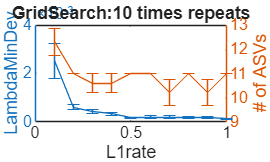

% Plot 1: LambdaMinDeviance and # of ASVs across L1 rates
figure;
yyaxis left
errorbar(alphas(1:end),LambdaMinDEvsMean(1:end),LambdaMinDEvsSEM(1:end))
ylabel('LambdaMinDev');
yyaxis right
errorbar(alphas(1:end),CoefsNumMean(1:end),CoefsNumSEM(1:end));
ylabel('# of ASVs');
xlabel('L1rate');
title(append('GridSearch:',num2str(size(repeat,2)),' times repeats'));

% Plot 2: Histogram of ASV appearance frequency per L1 rate

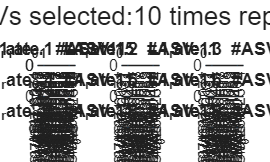

L1_ind=[1:10];
GS_selecASVs = cell(size(L1_ind,2),1);
tempAlphas=arrayfun(@(p1) alphas(p1), L1_ind', 'UniformOutput', false);

for i=L1_ind
    tempASVs=[];
    for j=repeat
        tempASVs=[tempASVs GridASVs{i,j}];
    end
    GS_selecASVs{i-min(L1_ind)+1,1}=tempASVs;
end

GS_selecASVsCategory=arrayfun(@(p1) categorical(GS_selecASVs{p1-min(L1_ind)+1}), L1_ind', 'UniformOutput', false);
GS_selecASVsCountTable=arrayfun(@(p1) countlabels(GS_selecASVsCategory{p1-min(L1_ind)+1}), L1_ind', 'UniformOutput', false);

figure;
t = tiledlayout(ceil(size(L1_ind,2)/3),3);
for i = L1_ind-min(L1_ind)+1
    nexttile
    histogram(GS_selecASVsCategory{i,1});
    title(append('L1_rate_',num2str(cell2mat(tempAlphas(i,1))),' #ASV:',num2str(size(GS_selecASVsCountTable{i,1},1))));
end
sgtitle(append('ASVs selected:',num2str(size(repeat,2)),' times repeats'));

% Plot 3: Pairwise correlation of ASVs selected with >= appearanceRate frequency

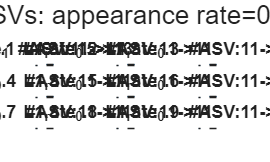

% (ASVs appearing in >= appearanceRate fraction of repeats are retained)
appearanceRate=0.8;
L1_ind=[1:10];
GS_extractedASVsInd = cell(size(L1_ind,2),1);
figure;
tt = tiledlayout(ceil(size(L1_ind,2)/3),3);
for i = L1_ind-min(L1_ind)+1
    nexttile
    idx = GS_selecASVsCountTable{i,1}.Count>=appearanceRate*size(repeat,2);
    extractedASVs = GS_selecASVsCountTable{i,1}.Label;
    extractedASVs=categories(extractedASVs);
    extractedASVs=extractedASVs(idx);
    idx2 = ismember(ASV', extractedASVs);
    GS_extractedASVsInd{i-min(L1_ind)+1,1}=idx2;
    extractedData=Xa(:,idx2);
    pcorr=corrcoef(extractedData);
    isupper = logical(triu(ones(size(pcorr)),1));
    pcorr(isupper) = NaN;
    h = heatmap(pcorr,'MissingDataColor','w');
    h.XDisplayLabels = ASV(idx2);
    h.YDisplayLabels = ASV(idx2);
    title(append('L1_rate_',num2str(cell2mat(tempAlphas(i,1))),...
        ' #ASV:',num2str(size(GS_selecASVsCountTable{i,1},1)),...
        '->',num2str(size(extractedASVs,1))));
end
sgtitle(append('Pairwise corr of ASVs: appearance rate=',num2str(appearanceRate),' in ',num2str(size(repeat,2)),' repeats'));

% Plot 4: Refit GLM with consistently selected ASVs

GS_refitGlmAppearanceASV=arrayfun(@(p1) fitglm([X(:,GS_extractedASVsInd{p1-min(L1_ind)+1,1}),Y]), L1_ind', 'UniformOutput', false);

figure;
ttt = tiledlayout(ceil(size(L1_ind,2)/3),3);
for i = L1_ind-min(L1_ind)+1
    nexttile
    ypred = predict(GS_refitGlmAppearanceASV{i},Xa(:,GS_extractedASVsInd{i,1}));
    scatter(ypred,Ya,10,'filled');
    title(append('L1_rate_',num2str(cell2mat(tempAlphas(i,1))),...
        ' Rsq:', num2str(sprintf("%.3f",round(GS_refitGlmAppearanceASV{i}.Rsquared.Ordinary,3))),...
        ' #ASV:',num2str(size(GS_selecASVsCountTable{i,1},1)),...
        '->', num2str(GS_refitGlmAppearanceASV{i}.NumPredictors)));
    xlabel('Predicted');
    ylabel('True');
end
sgtitle(append('Refit GLM: appearance rate=',num2str(appearanceRate),' in ',num2str(size(repeat,2)),' repeats'));

1.1-3  Fit GLM with consistently selected ASVs

*** Set Selected_L1rate in the code block below after inspecting 1.1-2 plots ***

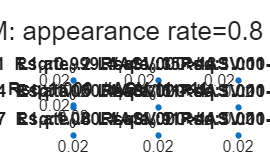

% Inspect the plots from section 1.1-2, then set Selected_L1rate below.
% Choose a value that balances low deviance with a manageable # of ASVs.

% Must be one of: 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1.0
Selected_L1rate= .8

index = find(alphas==Selected_L1rate);
sifted_inex=index-min(L1_ind)+1;
glm=GS_refitGlmAppearanceASV{sifted_inex};
coef=glm.Coefficients{2:end,"Estimate"};

Selected_L1rate = 0.8000

intercept=glm.Coefficients{1,"Estimate"};
std_coef=coef.*sqrt(var(Xa(:,GS_extractedASVsInd{sifted_inex}))./var(Ya))';
Y_pred=predict(GS_refitGlmAppearanceASV{sifted_inex},Xa(:,GS_extractedASVsInd{sifted_inex}));

1.1-3 (cont.)  Standardized coefficient bar plot

% Plot standardized coefficients for the selected L1 rate
figure
bar(glm.VariableNames(1:end-1),std_coef);
title(append('GML after Lassoglm: L1 rate ',num2str(Selected_L1rate)))
xlabel('ASV');
ylabel('std_coef');

1.1-4  R2 reduction per ASV

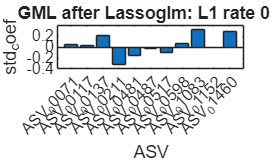

% R2 reduction (approach 1): temporarily zero each coefficient and
% measure the drop in R2. Larger drop = greater contribution to fit.
coef1=coef;
r2_reduce = double.empty;
for i=1:size(coef1,1)
    coef1(i)=0;
    r2_1 = py.sklearn.metrics.r2_score(Ya, Xa(:,GS_extractedASVsInd{sifted_inex})*coef1+intercept);

    r2_reduce=[r2_reduce,[glm.Rsquared.Ordinary-r2_1]];
    coef1(i)=coef(i);
end
figure,
bar(glm.VariableNames(1:end-1),r2_reduce);
xlabel('ASV');
ylabel('R2_reduciton');

1.1-5  Scatter plots of each ASV vs morphometric trait

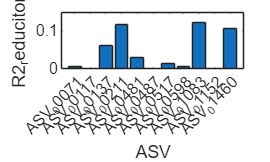

% Scatter plot of each selected ASV (log2 abundance) vs morphometric trait.
% Colors: red=BrineShrimp, green=Spirulina, black=Guano
% Regression lines:
%   blue (solid)    : fit using all samples
%   magenta (dashed): fit using non-zero samples only
%
% Update diet labels below if applying to a different experiment.

t = tiledlayout(ceil(size(coef,1) / 5), 5);

X_selected = Xa(:, GS_extractedASVsInd{sifted_inex});

% Diet group indices
ind_BS = ismember(T.diet, 'BrineShrimp');
ind_SP = ismember(T.diet, 'Spliru');
ind_GU = ismember(T.diet, 'Guano');

% If Mapper node filtering was applied, use the filtered subset
if exist('file', 'var') && exist('file2', 'var')
    ind_BS = ismember(T(clusters', :).diet, 'BrineShrimp');
    ind_SP = ismember(T(clusters', :).diet, 'Spliru');
    ind_GU = ismember(T(clusters', :).diet, 'Guano');
end

% Arrays to store R2 and p-values for the output table
R_sq_all_vals      = NaN(size(coef, 1) + 1, 1);
R_sq_nonzero_vals  = NaN(size(coef + 1, 1), 1);
p_value_all_vals   = NaN(size(coef + 1, 1), 1);
p_value_nonzero_vals = NaN(size(coef + 1, 1), 1);
nonzero_count_vals = NaN(size(coef + 1, 1), 1);
ASV_names          = cell(size(coef + 1, 1), 1);

R_sq_all_vals(1:1)      = NaN;
R_sq_nonzero_vals(1:1)  = NaN;
p_value_all_vals(1:1)   = NaN;
p_value_nonzero_vals(1:1) = NaN;
nonzero_count_vals(1:1) = NaN;

for i = 1:size(coef,1)
    nexttile;

    % Scatter plot colored by diet
    scatter(Ya(ind_BS), X_selected(ind_BS, i), 10, 'r', 'filled'); % BrineShrimp
    hold on;
    scatter(Ya(ind_SP), X_selected(ind_SP, i), 10, 'g', 'filled'); % Spirulina
    scatter(Ya(ind_GU), X_selected(ind_GU, i), 10, 'k', 'filled'); % Guano

    % Regression: all samples (blue)
    mdl_all     = fitlm(Ya, X_selected(:, i));
    R_sq_all    = mdl_all.Rsquared.Ordinary;
    p_value_all = mdl_all.Coefficients.pValue(2);
    plot(Ya, predict(mdl_all, Ya), 'b', 'DisplayName', sprintf('R^2 (all)=%.4f', R_sq_all));

    % Regression: non-zero samples only (magenta dashed)
    nonzero_idx = X_selected(:, i) > 0;
    Ya_nonzero  = Ya(nonzero_idx);
    X_selected_nonzero = X_selected(nonzero_idx, i);
    if ~isempty(Ya_nonzero) && ~isempty(X_selected_nonzero)
        mdl_nonzero     = fitlm(Ya_nonzero, X_selected_nonzero);
        R_sq_nonzero    = mdl_nonzero.Rsquared.Ordinary;
        p_value_nonzero = mdl_nonzero.Coefficients.pValue(2);
        plot(Ya_nonzero, predict(mdl_nonzero, Ya_nonzero), 'm--', ...
            'DisplayName', sprintf('R^2 (non-zero)=%.4f', R_sq_nonzero));
    end

    lsline_handle = lsline;
    lsline_handle(1).Color = 'k'; lsline_handle(1).LineStyle = '--';
    lsline_handle(2).Color = 'g'; lsline_handle(2).LineStyle = '--';
    lsline_handle(3).Color = 'r'; lsline_handle(3).LineStyle = '--';

    xlabel(s);
    ylabel(append(glm.VariableNames(i), '_Log2'));

    % Title: R2 (non-zero) in magenta, R2 (all) in blue
    title_str = sprintf('R^2 (non-zero)=%.4f\nR^2 (all)=%.4f', R_sq_nonzero, R_sq_all);
    t_title = title(title_str);
    t_title.String = strrep(t_title.String, 'R^2 (non-zero)', ['\color{magenta} R^2 (non-zero)']);
    t_title.String = strrep(t_title.String, 'R^2 (all)', ['\color{blue} R^2 (all)']);

    R_sq_all_vals(i + 1)      = R_sq_all;
    R_sq_nonzero_vals(i + 1)  = R_sq_nonzero;
    p_value_all_vals(i + 1)   = p_value_all;
    p_value_nonzero_vals(i + 1) = p_value_nonzero;
    nonzero_count_vals(i + 1) = sum(nonzero_idx);
    ASV_names{i + 1}          = append(glm.VariableNames{i}, '_Log2');
end

results_table = table(ASV_names, R_sq_all_vals, p_value_all_vals, R_sq_nonzero_vals, p_value_nonzero_vals, nonzero_count_vals, ...
    'VariableNames', {'ASV_Name', 'R2_all', 'p_value_all', 'R2_nonzero', 'p_value_nonzero', 'nonzero_count'});

1.1-6  Save results

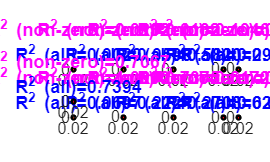

% Compile output table: ASV names, coefficients, SE, t-values, p-values,
% R2 reduction, and per-ASV regression statistics.
% A save dialog opens to choose the output filename and location.


% Simplify ASV names by removing leading zeros (e.g. ASV_001 -> ASV_1)
glmASV_selected=glm.CoefficientNames';
glmASV_selected=strrep(glmASV_selected,'_0000','_');
glmASV_selected=strrep(glmASV_selected,'_000','_');
glmASV_selected=strrep(glmASV_selected,'_00','_');
glmASV_selected=strrep(glmASV_selected,'_0','_');

glmCoefficients=glm.Coefficients.Estimate;
glmSE=glm.Coefficients.SE;
glmT_values=glm.Coefficients.tStat;
glmP_values=glm.Coefficients.pValue;

% X_selected: log2-transformed abundance of selected ASVs
X_selected=Xa(:,GS_extractedASVsInd{sifted_inex});
glm_numSamplesThan0=[0;(sum(X_selected>0))'];
glm_r2_Reduction1=[0 r2_reduce]';

out_table1= table(glmASV_selected,glmCoefficients,glmSE,glmT_values,glmP_values,glm_numSamplesThan0,glm_r2_Reduction1);
out_table1 = [out_table1, results_table(:,2:6)];

if exist('file') & exist('file2')
    glm_outdata_ASV=cat(2,T(clusters',1:morp_ind),T(clusters',glm.PredictorNames));
else
    glm_outdata_ASV=cat(2,T(:,1:morp_ind),T(:,glm.PredictorNames));
end

if exist('file') & exist('file2')
    save_file_name=append('ML_glm_L1_',num2str(Selected_L1rate),'_rep_',num2str(appearanceRate),'_',pop2,'_',s,'_','_',erase(erase(erase(erase(file,'.pickle'),gut),pop2),s),'_',erase(erase(erase(erase(file2,'.txt'),gut),pop2),s), '_coeffs.csv');
    if contains(file2,erase(file,'.pickle'))==1
        save_file_name=append('ML_glm_L1_',num2str(Selected_L1rate),'_rep_',num2str(appearanceRate),'_',pop2,'_',s,'_','_',erase(erase(erase(erase(file2,'.txt'),gut),pop2),s), '_coeffs.csv');
    end
    save_file_name=strrep(save_file_name,'___','_');
    save_file_name=strrep(save_file_name,'__','_');
    save_file_name=strrep(save_file_name,'_nodes','');
    save_file_name=strrep(save_file_name,'KMeans','KM');
    save_file_name=strrep(save_file_name,'clusters=2','clu2');
    save_file_name=strrep(save_file_name,'cube','cu');
    save_file_name=strrep(save_file_name,'StandardLength','SL');
    save_file_name=strrep(save_file_name,'TotalGutLength','TGL');
    save_file_name=strrep(save_file_name,'HindgutLength','HGL');
    save_file_name=strrep(save_file_name,'MidgutWidth','MGW');
    save_file_name_ASV= strrep(save_file_name,'_coeffs.csv','_ASVs.csv');
    [fileout,pathout,indx] = uiputfile(save_file_name,...
      'save file',append(path2,save_file_name));
    save_file_name_workspace=strrep(save_file_name,'_coeffs.csv','.mat');
    writetable(out_table1,append(pathout,save_file_name));
    writetable(glm_outdata_ASV,append(pathout,save_file_name_ASV));
    save(append(pathout,save_file_name_workspace));
else
    save_file_name=append('ML_L1_',num2str(Selected_L1rate),'_rep',num2str(appearanceRate),'_',pop2,'_',s,'_all_coeffs.csv');
    save_file_name_ASV=append('ML_L1_',num2str(Selected_L1rate),'_rep',num2str(appearanceRate),'_',pop2,'_',s,'_all_ASVs.csv');
    [fileout,pathout,indx] = uiputfile(save_file_name,...
      'save file',append('',save_file_name));
    save_file_name_workspace=append(pathout,'ML_L1_',num2str(Selected_L1rate),'_rep_',num2str(appearanceRate),'_',pop2,'_',s,'_all.mat');
    writetable(out_table1,append(pathout,save_file_name));
    writetable(glm_outdata_ASV,append(pathout,save_file_name_ASV));
    save(save_file_name_workspace);
end